## AAE334 lab2 MATLAB CODE

clear all; close all; clc;

### 2-1

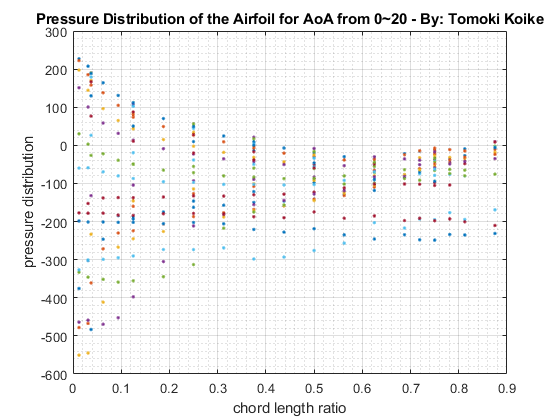

% Import the excel sheets 
P_dist_data = readmatrix("pressure_dist_allAoAs.xlsx");
chord_len = P_dist_data(1,2:end);
P_dists = psi2pascal(P_dist_data(2:end,2:end));  % pascals
% Plotting 
fig1 = figure("Renderer","painters");
plot(chord_len,P_dists(1,:),'.')
xlabel('chord length ratio')
ylabel('pressure distribution')
title('Pressure Distribution of the Airfoil for AoA from 0~20 - By: Tomoki Koike')
hold on
for i = 2:size(P_dists,1)
    plot(chord_len, P_dists(i,1:end),'.')
end
hold off
grid on
grid minor 
box on 
saveas(fig1, 'pressure_dist.png')

### 2-2

% Creating matrix with pressure coefficients 
rho = 1.225;  % kg/m^3
v = 19.17;  % m/s
Cp = P_dists./(0.5*rho*v^2);
Cp_u = Cp(:,1:19);
Cp_l = Cp(:,20:end);

% Import data of xy-coordinates
xy_coord = readmatrix("naca66215_xy_coord.xlsx");
xy_coord_u = xy_coord(1:71,:);  % upper surface
xy_coord_l = xy_coord(72:end,:);  % lower surface
x_u_interp = [0.0125 0.03125 0.0625 0.09375 0.125 0.1875 0.25 0.3125 0.375...
    0.4375 0.5 0.5625 0.625 0.6875 0.71875 0.75 0.78125 0.8125 0.875];
x_l_interp = [0.0375 0.125 0.25	0.375 0.5 0.625	0.75];
y_u = xy_coord_u(:,2);
y_l = xy_coord_l(:,2);
x_u = xy_coord_u(:,1);
x_l = xy_coord_l(:,1);
% interpolate
y_u_interp = interp1(x_u,y_u,x_u_interp);
y_l_interp = interp1(x_l,y_l,x_l_interp);

% Calculating Cn, Ca, Cl, and Cd
alpha = -8:2:20;

alpha =     -8    -6    -4    -2     0     2     4     6     8    10    12    14    16    18    20


Cn = zeros([1, length(alpha)]);
Ca = zeros([1, length(alpha)]);
Cl = zeros([1, length(alpha)]);
Cd = zeros([1, length(alpha)]);

ct = 1

ct = 1

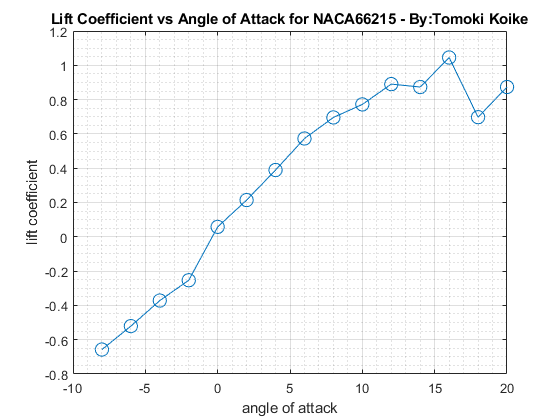

x_u_interp = [x_u_interp 0.925];
dx_u = diff(x_u_interp);
x_l_interp = [x_l_interp 0.875];
dx_l = diff(x_l_interp);
for m = alpha
    % for AoA of m degrees
    Cn(ct) = sum(Cp_l(ct,:).*dx_l) - sum(Cp_u(ct,:).*dx_u);
    Ca(ct) = sum(Cp_u(ct,:).*gradient(y_u_interp).*dx_u)...
        - sum(Cp_l(ct,:).*gradient(y_l_interp).*dx_l);
    Cl(ct) = Cn(ct)*cosd(m) - Ca(ct)*sind(m);
    Cd(ct) = Cn(ct)*sind(m) + Ca(ct)*cosd(m);
    ct = ct + 1;
end

% Plotting the results
fig2 = figure("Renderer","painters");
plot(alpha, Cl, 'o-', 'MarkerSize', 10)
xlabel('angle of attack')
ylabel('lift coefficient')
title('Lift Coefficient vs Angle of Attack for NACA66215 - By:Tomoki Koike')
grid on 
grid minor
box on
saveas(fig2, 'Cl_vs_alpha.png');

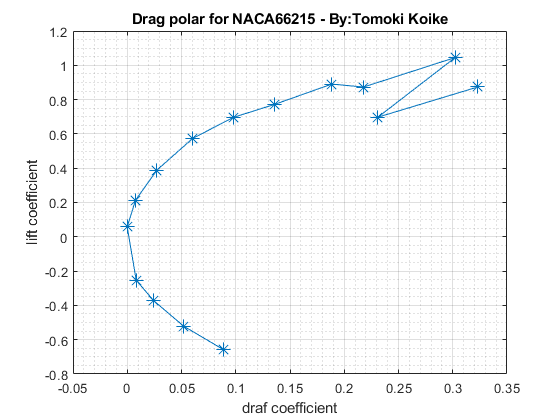


fig3 = figure("Renderer","painters");
plot(Cd, Cl, '*-', 'MarkerSize', 10)
xlabel('draf coefficient')
ylabel('lift coefficient')
title('Drag polar for NACA66215 - By:Tomoki Koike')
grid on 
grid minor
box on
saveas(fig3, 'drag_polar.png');

### Functions 

function p_new = psi2pascal(p)
    p_new = p*6894.76;
end